addpath('Kinematics')
addpath('Kinetics')
addpath('Control System')

supressed_print= evalc('run Linearize_EOMs.mlx'); %Run the script to generate the equations of motion for the Ball and Plate in terms of the u-joint torques

clear supressed_print

sympref('FloatingPoint',true);

# Linear Moving Setpoint Controller

The feasibility of a setpoint controller for trajectory tracking is explored in this script. A traditional setpoint controller architecture is employed but the setpoint is not simple. The setpoint is chosen as the desired trajectory in x and y as functions of time. 

## Reformulate the System as Two Decoupled, Fourth Order, Single Input Systems

A system with state vector $\tilde{x}_{1} $:


$$\tilde{x}_{1} = [x  ~\beta ~\dot{x}~\dot{\beta}]^T

$$


And state equation:


$$\dot{\tilde{x}}_{1} = A_{1} \tilde{x}_{1} + B_{1}\tilde{u}_{1}$$


A1 = A_uc(1:4,1:4)

$$A1 = \left[\begin{array}{cccc} 0 & 1 & 0 & 0\\ -5.2170 & 0 & 4.0111 & 0\\ 0 & 0 & 0 & 1\\ 112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

B1 = B_uc(1:4,1)

$$B1 = \left[\begin{array}{c} 0\\ -17.7268\\ 0\\ 383.5785 \end{array}\right]$$

And another system with state vector $\tilde{x}_{2} $:


$$\tilde{x}_{2} = [y~\gamma~\dot{y}~\dot{\gamma}]^T$$


And state equation:


$$\dot{\tilde{x}}_{2} = A_{2} \tilde{x}_{2} + B_{2}\tilde{u}_{2}$$


A2 = A_uc(5:8,5:8)

$$A2 = \left[\begin{array}{cccc} 0 & 1 & 0 & 0\\ -5.2170 & 0 & -4.0111 & 0\\ 0 & 0 & 0 & 1\\ -112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

B2 = B_uc(5:8,2)

$$B2 = \left[\begin{array}{c} 0\\ 17.7268\\ 0\\ 383.5785 \end{array}\right]$$

## Create Data and Functions for Simulation (Moving Setpoint Controller)

Using an augmented state vector this time:


$$\tilde{x}_{1} = [x  ~\beta ~\dot{x}~\dot{\beta} 
\int_{0}^{t}\delta_xdt~]^T

$$


Where 


$$\delta_x = \bar{x} - x$$


and $\bar{x}$ is the desired setpoint

A1a = [A1,zeros(4,1);[-1 0 0 0 0]] %Augmented A Matrix

$$A1a = \left[\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ -5.2170 & 0 & 4.0111 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 112.8871 & 0 & 64.8295 & 0 & 0\\ -1 & 0 & 0 & 0 & 0 \end{array}\right]$$



A1_sim = double(A1);
B1_sim = double(B1);
C1_setp_ctrl = [1 0 0 0]; %Only care about controlling the position to the desired trajectory through setpoint control (for now)

Full State Feedback Matrices (Want to give the system some light damping but no oscillatory behavior for the setpoint controller to resonate with - it is oscillliatory itself)

K1 = place(A1_sim,B1_sim, [-3.6 -3.5 -4 -4.5]); %Because why not...I'm just gonna try it out

PI Controller

%Gains for PI contorller
KI = .08;
KP = .09;

Moving Setpoint Parameters

r_sim = 45; % radius of circular trajectory [mm]
omega_sim = .25; %angular frequency of circular trajectory [mm]

des_traj_sym(t) = r_sim*sin(omega_sim*t)

$$des\_traj\_sym(t) = 45\,\sin\left(0.2500\,t\right)$$

Overlay a fist order response so that the desired trajectory is reached gradually (trying to remove dirac delta function from the feed forward actuation solution)

T = (2*pi/omega_sim)/5 %Time constant of the first order response that smooths out the trajectory

T = 5.0265

des_traj_sym(t) = (1 - exp(-(t/T)))*des_traj_sym

$$des\_traj\_sym(t) = -45\,\sin\left(0.2500\,t\right)\,\left({\mathrm{e}}^{-0.1989\,t}-1\right)$$

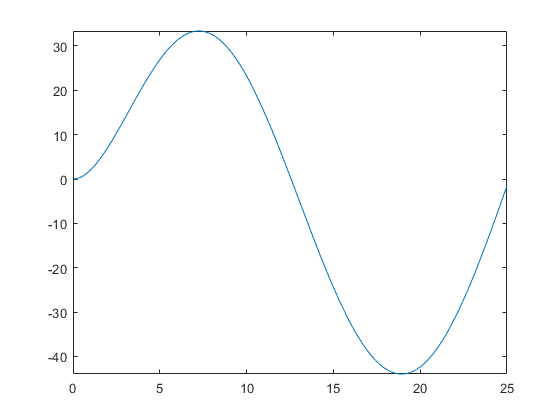

fplot(des_traj_sym)
xlim([0 25])

Take laplace transform of the desired trajectory

des_traj_sym_lapl(s) = laplace(des_traj_sym)

$$des\_traj\_sym\_lapl(s) = \frac{45\,\left(1.0053e+03\,s+100\right)}{1.0106e+04\,s^{4}+4.0212e+03\,s^{3}+1.6633e+03\,s^{2}+251.3274\,s+64.4784}$$

Analytically determine the feed forward actuation from the inverse of the plant transfer function - use the Laplace transformation method:

FF_act_sym_lapl(s) = des_traj_sym_lapl*Plant_Inv_TF_sym

Unrecognized function or variable 'Plant_Inv_TF_sym'.

FF_act_sym(t) = ilaplace(FF_act_sym_lapl)

Create a matlab functions from the time domain actuation result:

% FF_act_handle = @(t) 0.9787*cos(0.2500.*t) + 3.7005*sin(0.2500.*t) - 0.3978*cosh(12.3135.*t) - 0.3417*sinh(12.3135.*t) - 0.8334*exp(-0.1989.*t)*(cos(0.2500.*t) + 3.5847*sin(0.2500.*t))
FF_act_handle = matlabFunction(FF_act_sym)

fplot(FF_act_handle)
% xlim([0 25])

## Simulate the Controller

%Specify simulation time
t_sim = 55;
%Specify initial conditions
x1_0 = [0 0 0 0]; %As if the ball was at rest in the center of the plate - the control objective of any regulator designed for the system
%Select setpoint type
SP_sel = 1; %Sinusoidal input

out = sim('Linear_Moving_Setpoint')